# Week01  

Nian Luisman 

## 1 Sampling

1.1 Sampled time Generate an array representing the sampled time

 𝑡[𝑛] = {0, 𝑇, 2𝑇, 3𝑇, 4𝑇, … 𝑛𝑇} 

Where 𝑇 is the sampling period. The array should represent the time between 0 and 2 seconds sampled at 1600Hz. What is the maximum frequency which can be present in a continuous signal such that the original signal can be reconstructed again from the sampled signal? Useful MATLAB command: linspace() Useful Python command: np.linspace() 

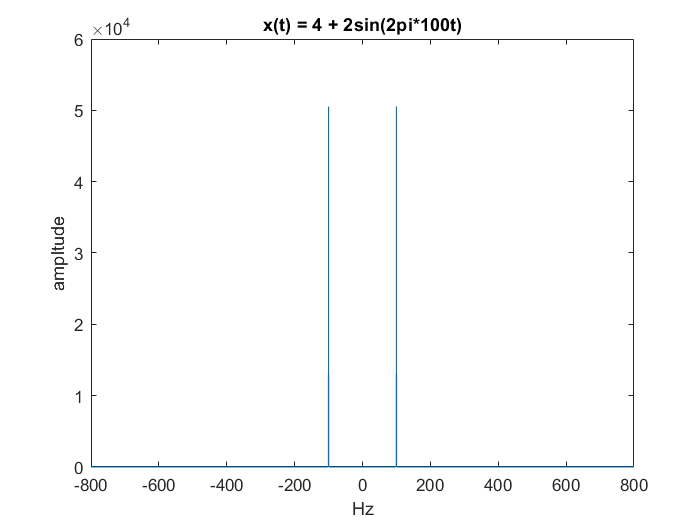

f = 1600; % sampling frequency
t = linspace(0,2, 2*f);  % time vector

y = 4 * 2*sin(2*pi*100*t);
spec = fft(y);

N = length(spec);


Y = fftshift(spec);
fshift = (-N/2:N/2-1)*(f/N); % zero-centered frequency range
powershift = abs(Y).^2/N;     % zero-centered power
plot(fshift,powershift)
title("x(t) = 4 + 2sin(2pi*100t)")
xlabel("Hz")
ylabel("ampltude")

## 2 Frequency spectrum

First, sketch the spectrum of the signal given below. After this use MATLAB/Python to show the doublesided frequency spectrum of the following signal, remember the sampling frequency is still 1600Hz. 

## 2.2 Double trouble

First, sketch the spectrum of the signal given below. After this use MATLAB/Python to show the doublesided frequency spectrum of the following signal, remember the sampling frequency is still 1600Hz. 

𝑥(𝑡) = 2 sin(2𝜋100𝑡) + 5cos (2𝜋1200𝑡) 

Does it match your sketch? If so; well done! If not; explain.

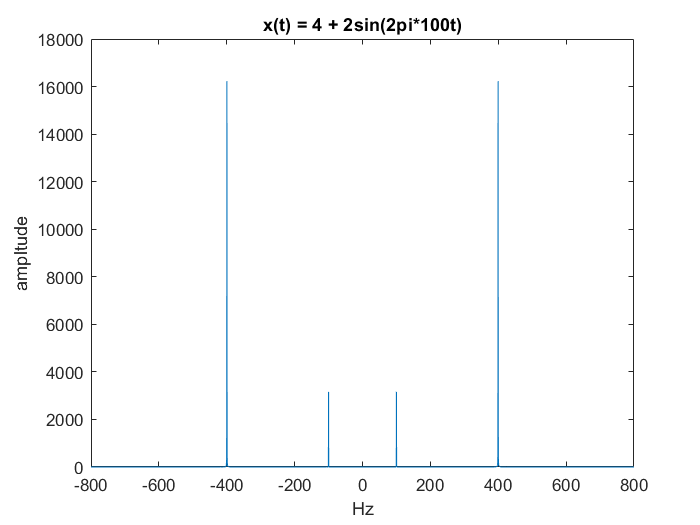

f = 1600; % sampling frequency
t = linspace(0,2, 2*f);  % time vector

y = 2*sin(2*pi*100*t) + 5*cos(2*pi*1200*t);
spec = fft(y);

N = length(spec);


Y = fftshift(spec);
fshift = (-N/2:N/2-1)*(f/N); % zero-centered frequency range
powershift = abs(Y).^2/N;     % zero-centered power
plot(fshift,powershift)
title("x(t) = 4 + 2sin(2pi*100t)")
xlabel("Hz")
ylabel("ampltude")

## 2.3 Square wave

Consider a 50Hz square wave (-2V, +2V). For this signal:

 • Plot the time-domain signal 

• Plot the single-sided frequency spectrum of this signal 

Motivate your choice for the sampling frequency and describe what observe in the frequency domain

Fs = 1000;                    %// Sampling frequency
freq = 50;
T = 1/Fs;                     %// Sample time
L = 1000;                     %// Length of signal
t = (0:L-1)*T;                %// Time vector

y = 2*square(sin(2*pi*freq*t))%// Make a square wave

y =      2     2     2     2     2     2     2     2     2     2     2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2     2     2     2     2     2     2     2     2     2     2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2     2     2     2     2     2     2     2     2     2


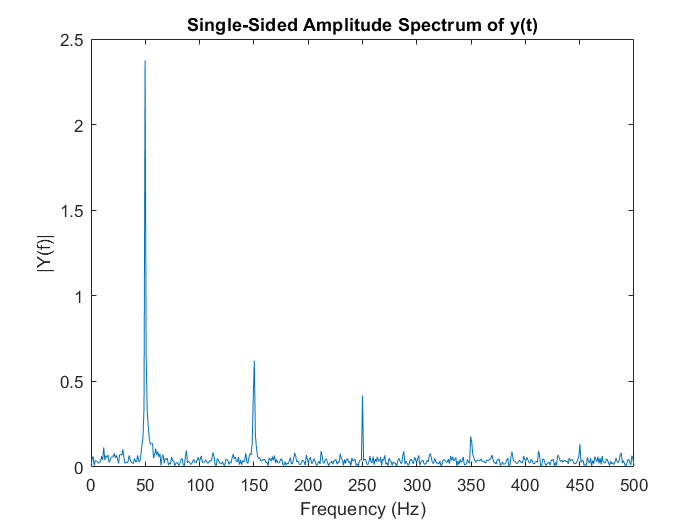


NFFT = 2^nextpow2(L);         %// Next power of 2 from length of y
Y = fft(y,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2+1);

%// Plot single-sided amplitude spectrum.
plot(f,2*abs(Y(1:NFFT/2+1))) 
title('Single-Sided Amplitude Spectrum of y(t)')
xlabel('Frequency (Hz)') %// probably would be more meaningful if you convert this to radians per second, check out the xtickmark and xtickmarklabel properties of plot
ylabel('|Y(f)|')

## test

n = -6:9;
Ts = 0.001;
tn = n*Ts;
xn = 20*cos(80*pi*tn-0.4*pi)

xn =   -18.5955  -16.1803  -12.7485   -8.5156   -3.7476    1.2558    6.1803   10.7165   14.5794   17.5261   19.3717   20.0000   19.3717   17.5261   14.5794   10.7165


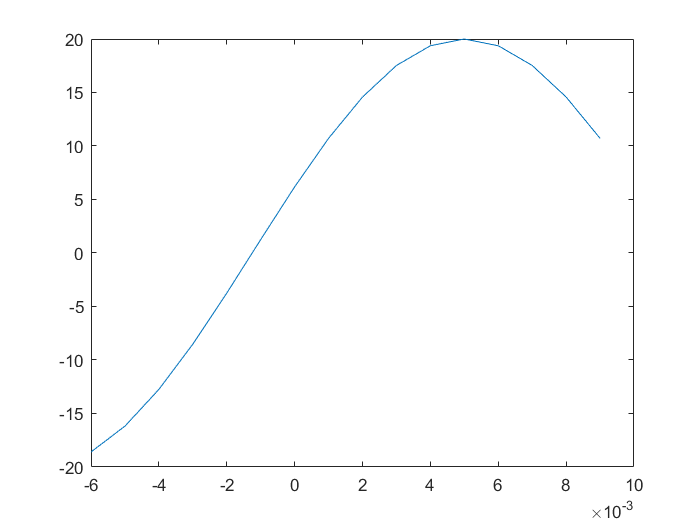

plot(tn,xn)